## Author: Arian Velayati, PhD

# 1D FEM simulator calculating the displacement in a bar fixed from one end and the reactive force at the fixed end in responce to the pulling force

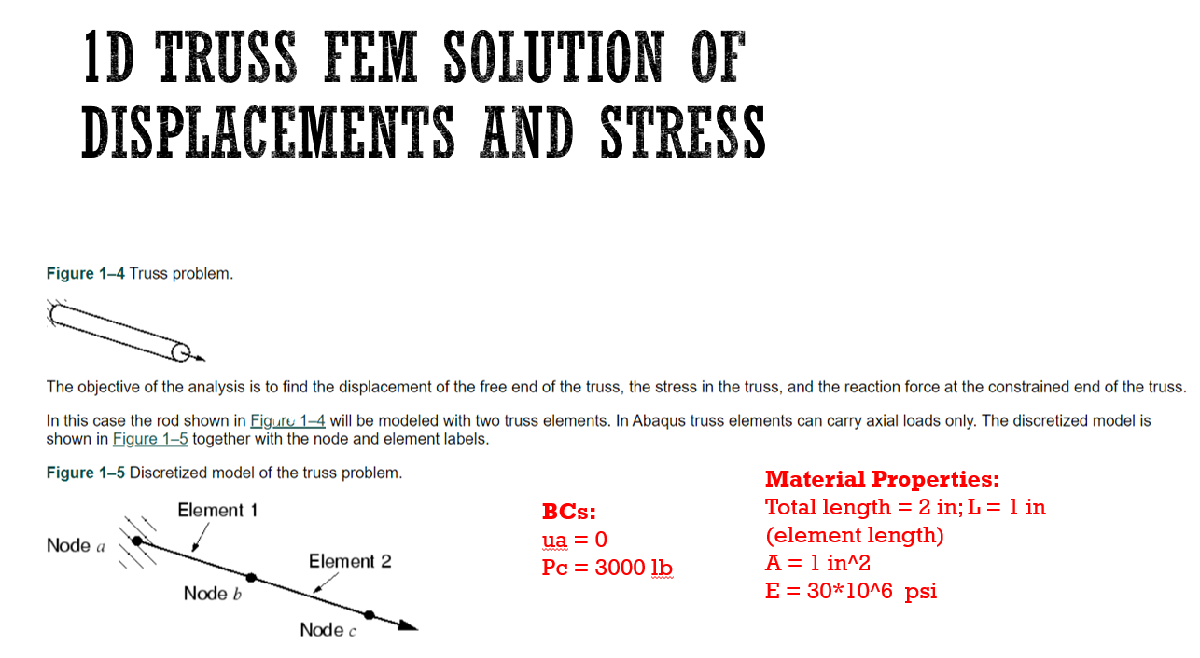

clear; close; clc;

## Material inputs

E = 30*10^6; % psi; Young's modulus (stifness modulus)
A = 1; % in2 (Cross sectional area of the bar)
L = 1; % in; Length of the element (Element's length)
P = 3000; %lb (External pull force)

## Boundary conditions

ua = 0; % u is displacement; ab,c are nodes: see the picture attached
Pc = P;
Pb = 0;

## Parameters and basic calculations

K = (E*A)/L; %lb/in

## Solver

Pm = [Pb;Pc];
Km = [2*K -K; -K K];

U = linsolve(Km,Pm) % in

U =    1.0e-03 *

    0.1000
    0.2000


R = K*(0-U(1)) % Reactive force at node 1; lb

R = -3000

fprintf('The reactive force at fixed pint/node a is (lb) : %i',  R)  % Prints each element on a new line

The reactive force at fixed pint/node a is (lb) : -3000

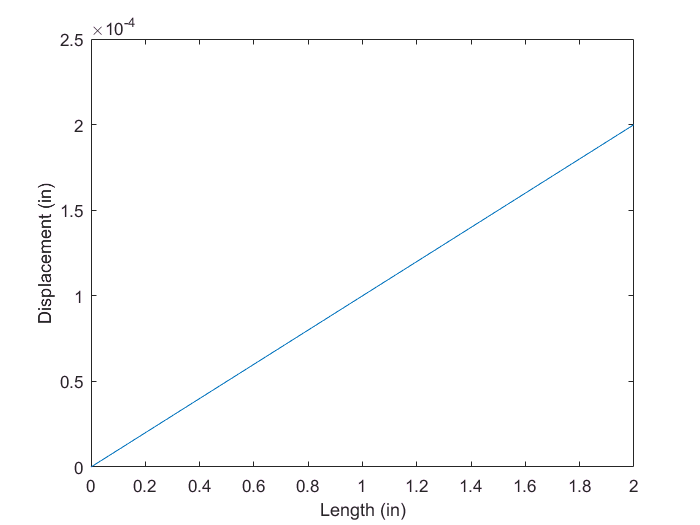

x = [0 L 2*L];
y = [0; U(1);U(2)];

plot(x,y)
xlabel('Length (in)')
ylabel('Displacement (in)')